# 多目标规划 序贯算法

本节课涉及的优化变量optimvar、优化问题optimproblem概念

MATLAB官方讲解：

[https://ww2.mathworks.cn/help/optim/ug/optimvar.html](https://ww2.mathworks.cn/help/optim/ug/optimvar.html)

[https://ww2.mathworks.cn/help/optim/ug/optim.problemdef.optimizationproblem.solve.html?searchHighlight=solve&s_tid=srchtitle_solve_2](https://ww2.mathworks.cn/help/optim/ug/optim.problemdef.optimizationproblem.solve.html?searchHighlight=solve&s_tid=srchtitle_solve_2)

当前模型：

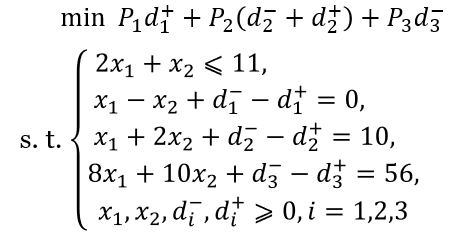

重要事项：课程里使用matlab 2023讲解的，没有问题。但使用2024版的却会出现和课程不一致的结果，这是因为matlab更改了默认算法，虽然官方声称“对于大部分问题性能更好”但其本身会带来不兼容性。**如果你使用的matlab是2024以及之后的版本，请进行以下修改：**

1、在序贯算法即本文件的“for i=1:3” 之前，插入一行代码：

opts = optimoptions("linprog",Algorithm ="dual-simplex-legacy");

这行代码在for循环之前已经写为注释了，取消注释百分号即可；

2、然后，把[sx,fval]=solve(p)，修改为[sx,fval]=solve(p,Options=opts); 

即指定使用更稳定的原算法

clc, clear
% 使用优化变量、优化问题来求解
% 创建优化变量x，dp和dm，类似于利用C++的类来创建对象
% 可以用来为目标函数和问题约束创建表达式
x = optimvar('x',2,'LowerBound',0);   % 定义两个变量x，最小值都为0
dp = optimvar('dp',3,'LowerBound',0); % 定义3个正偏差变量dp，最小值都为0
dm = optimvar('dm',3,'LowerBound',0); % 定义3个负偏差变量dm，最小值都为0

% 创建求最小值的优化问题p；optimproblem创建优化类问题
p=optimproblem('ObjectiveSense','min');

设置约束条件：$
2 x_{1}+x_{2} \le11  \\
x_{1}-x_{2}+d_{1}^{-}-d_{1}^{+}=0 \\
x_{1}+2 x_{2}+d_{2}^{-}-d_{2}^{+}=10 \\
8 x_{1}+10 x_{2}+d_{3}^{-}-d_{3}^{+}=56
$

% 设置优化问题的约束条件
p.Constraints.cons1 = ( 2*x(1)+x(2)<=11 );
% 注意，表示相等关系用的符号是"=="
p.Constraints.cons2=[x(1)-x(2)+dm(1)-dp(1)==0       
                     x(1)+2*x(2)+dm(2)-dp(2)==10
                     8*x(1)+10*x(2)+dm(3)-dp(3)==56];

设置目标函数：$\min P_{1} d_{1}^{+}+P_{2}\left(d_{2}^{-}+d_{2}^{+}\right)+P_{3} d_{3}^{-}$

% 设置目标函数
obj=[dp(1); dm(2)+dp(2); dm(3)];
% 单级目标函数的最优值goal，初始设为足够大的数
% 非常宽松的约束就等于没有约束，确保第一级的正常运算
goal=100000*ones(3,1);

% 2024版以及之后的matlab需要设定算法dual-simplex-legacy
%opts = optimoptions("linprog",Algorithm ="dual-simplex-legacy");
for i=1:3
    % 重要：更新上一级的最优值，作为该级的约束条件;
    p.Constraints.cons3=[obj<=goal];
    p.Objective=obj(i);
    % 2024或之后的版本把下一行改成 [sx,fval]=solve(p,Options=opts);
    [sx,fval]=solve(p);     % 针对优化问题使用solve，会自动选择求解方式
    %[sx,fval]=solve(p,Options=opts);     
    fprintf('第%d级目标求解为：\n',i)
    fval, xx=sx.x, sdm=sx.dm, sdp=sx.dp
    goal(i)=fval;
end

将使用 linprog 求解问题。

找到最优解。



第1级目标求解为：


fval = 0

xx =          0
    5.6000


sdm =     5.6000
         0
         0


sdp =          0
    1.2000
         0


将使用 linprog 求解问题。

找到最优解。



第2级目标求解为：


fval = 0

xx =     3.3333
    3.3333


sdm =      0
     0
     0


sdp =      0
     0
     4


将使用 linprog 求解问题。

找到最优解。



第3级目标求解为：


fval = 0

xx =      2
     4


sdm =      2
     0
     0


sdp =      0
     0
     0


#### 代码中的solve()用来求解优化类问题，会自动判断问题类型并调用默认求解器

#### 求每一级目标（i=1，2，3）时相应变化的约束条件见PPT

三级都求完了，迭代结束，求得满意解为${\;x}_1 =2,x_2 =4$。即应该安排每天生产2台设备Ⅰ，4台设备Ⅱ。

注意多目标规划求得的叫做“满意解”而不是“最优解”，多目标规划的最终解没有最优的概念。因为在求解过程中，三个目标的重要性的设定是具有主观性的，假如改变三个目标的重要性排序，那么求解结果也会变。

本文件出自b站/公众号：数学建模BOOM

关注公众号：数学建模BOOM，回复"购买"，获取全套视频课程+配套PPT课件

+代码文件+完善售后服务+后续课程更新

注意，文件开头强调了，如果使用2024以及之后的版本，需要按说明的修改。以下是matlab官方的说法：

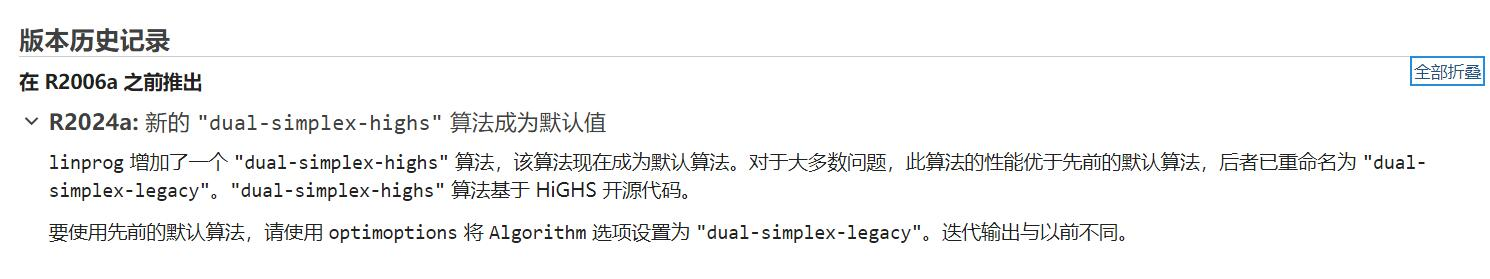

虽然官方说性能更优……但matlab本身不开源，也不知道它这算法到底怎么样，会和原本算法结果不一样。“对大多数问题，此算法性能优于先前默认”，但这也意味着不稳定，毕竟先前版本算法本身并没有问题，新的经受的考验又少，难以确保会有什么bug。